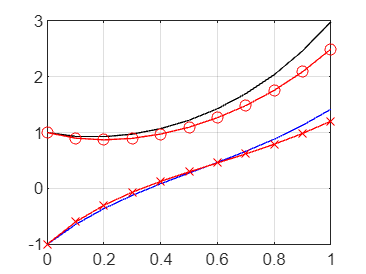

clear 
tspan = [0; 1];
y1 = [1;-1];
n = 10;
[t,y] = odeEuler(@funkEx142,tspan,y1,n);
% Analytisk lösning
c1 = 1/5;
c2 = 3/5;
Y= c1*[2;1]*exp(2*t) + c2*[1;-2]*exp(-3*t);
clf
plot(t,Y(1,:),'k')
hold on, grid on
plot(t,y(1,:),'r-o')
plot(t,Y(2,:),'b')
plot(t,y(2,:),'r-x')
hold off

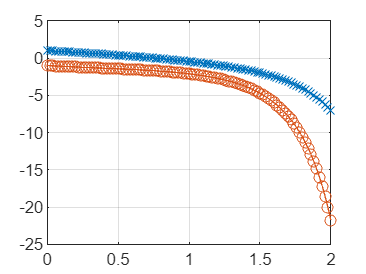

%Ex: 14.3a
clear
%funkEx143a(1,[1.3; 3])
tspan = [0,2];
ybv = [1; -1];
n = 100;
[t,y] = odeEuler(@funkEx143a,tspan,ybv,n);
clf
plot(t,y(1,:),'-x')
hold on
plot(t,y(2,:),'-o')
grid on
hold off

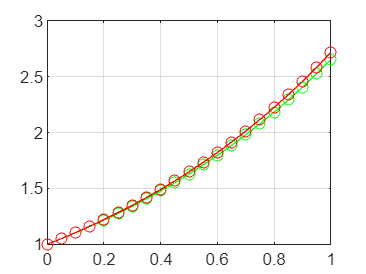

clear 
t = linspace(0,1,100);
c = 1;
y = c*exp(t);
n = 20;
% Berakna numeriska losningar 
[t1,y1]  = odeEuler(@funkEx1,[0,1],1,n);
[t2,y2]  = odeEuler(@funkEx1,[0,1],1,2*n);
[t5,y5]  = odeEuler(@funkEx1,[0,1],1,4*n);
[t3,y3]  = odeRK2(@funkEx1,[0,1],1,n);
[t4,y4]  = odeRK2(@funkEx1,[0,1],1,2*n);
[t6,y6]  = odeRK2(@funkEx1,[0,1],1,4*n);
[t7,y7]  = odeRK4(@funkEx1,[0,1],1,2*n);
% Plotta och jamfor 
clf
plot(t,y,'b')
grid on 
hold on
plot(t1,y1,'g-o')
plot(t3,y3,'r-o')